# Análise das distribuições no disco rotor

### com velocidade de avanço

clc
clear
close all

#### Características do rotor

Nb = 2;
Span = 9.144;


RootBladeDistance = 0.15*Span;
theta = 15.8;
twist_rate = -10/Span;
chord = 0.61;

**outros**

density = 1.225;

mass_payload = 0;
vehicle_position = [0; 0; 0];
vehicle_orientation = [0; 0; 0];

vehicle_velocity = [59.16; 0; 0];

azimutal_points =300;
No_elements = 500;

RPM = 205;

induced_velocity = -1;

blade_integrator =  'Trapezoidal';  %'Boole' %;  % 'Rectangle'; %'Simpson';

sim_init_rotor_simulation
[F_rotor, T_rotor, rotor_distribution_data] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);       
fprintf("\tF_rotor = %.4f |  %.4f |  %.4f \n", F_rotor)

	F_rotor = 491.6526 |  0.0000 |  136310.2924 


fprintf("\tT_rotor = %.4f |  %.4f |  %.4f \n", T_rotor)

	T_rotor = 378752.2418 |  0.0000 |  -8613.2424 


% fprintf("\tError: %.0f%% \n", abs(T-F_rotor(3))/T * 100)

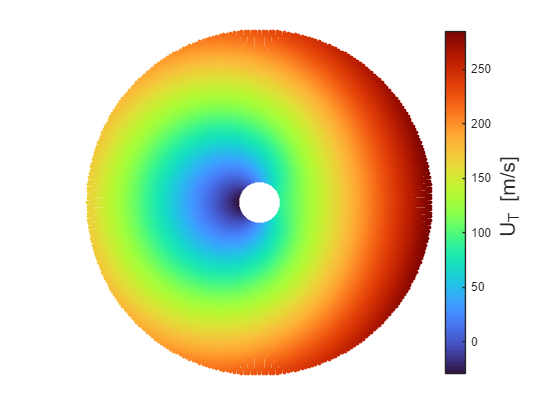

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_T;
end
polarPlot(azimutes, rho, values, "", " U_T [m/s]", "./studies/rotor_analysis/sim_B/plots/U_T.eps")

#### Velocidade Radial

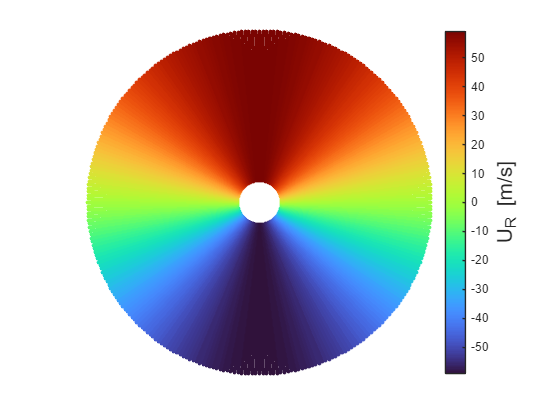

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_R;
end
polarPlot(azimutes, rho, values, "", "U_R [m/s]", "./studies/rotor_analysis/sim_B/plots/U_R.eps")

#### Velocidade Vertical

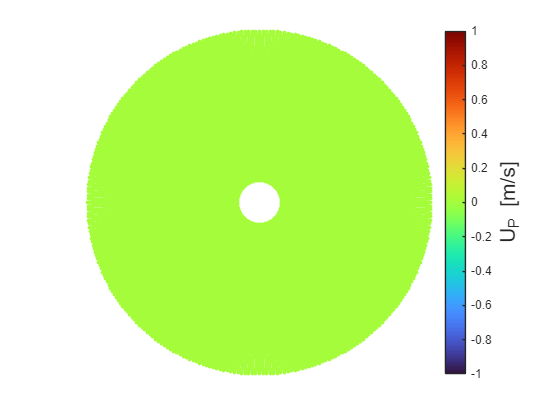

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).U_P;
end
polarPlot(azimutes, rho, values, "", "U_P [m/s]", "./studies/rotor_analysis/sim_B/plots/U_P.eps")

#### Módulo da velocidade 

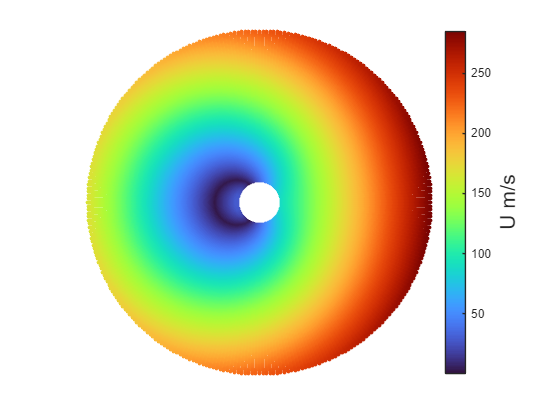

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).total_velocity;
end
polarPlot(azimutes, rho, values, "", "U m/s", "./studies/rotor_analysis/sim_B/plots/total_velocity.eps")

#### Modo de escoamento

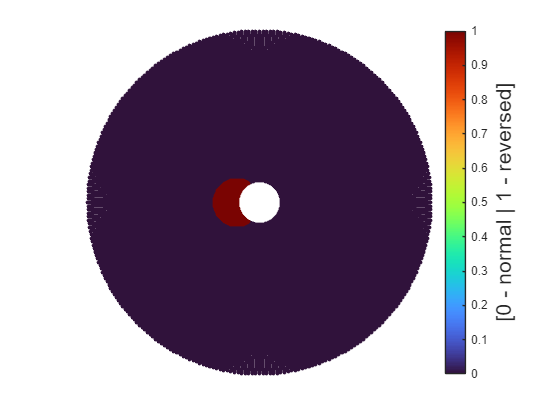

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).flow_mode;
end
polarPlot(azimutes, rho, values, "", "[0 - normal | 1 - reversed]", "./studies/rotor_analysis/sim_B/plots/flow_mode.eps")

#### Número de Reynolds

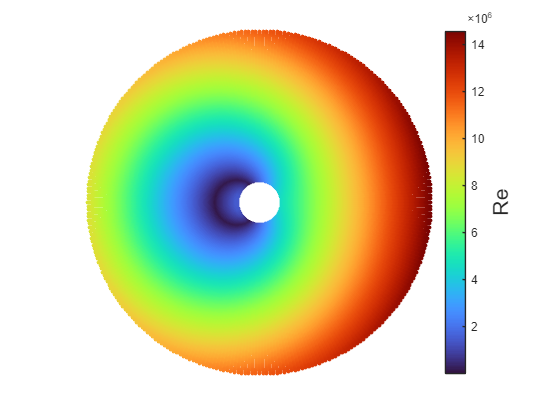

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Re;
end
polarPlot(azimutes, rho, values, "", "Re", "./studies/rotor_analysis/sim_B/plots/Re.eps")

#### Número de Mach

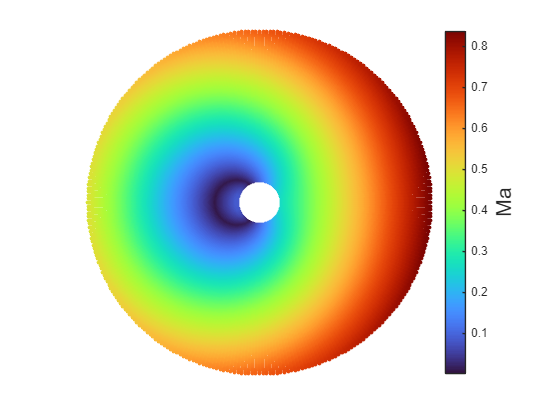

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Ma;
end
polarPlot(azimutes, rho, values, "", "Ma", "./studies/rotor_analysis/sim_B/plots/mach.eps")

#### Ângulo de picada

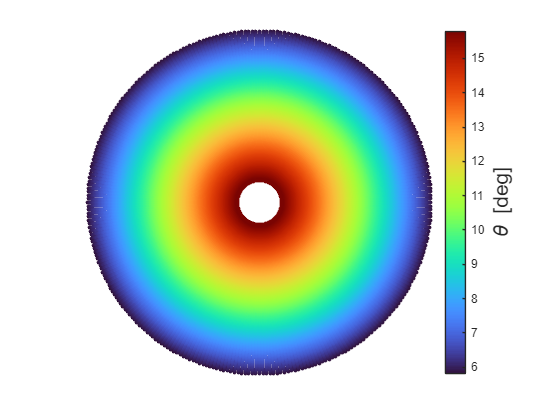

for i=1:length(azimutes)
    values(i, :) = BLADE.theta;
end
polarPlot(azimutes, rho, values, "", "\theta [deg]", "./studies/rotor_analysis/sim_B/plots/theta.eps")

#### Ângulo de incidência

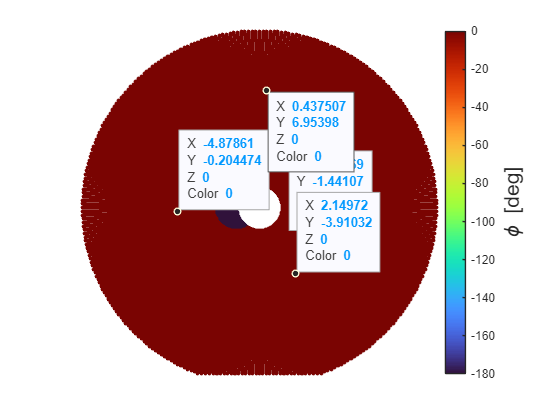

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).phi;
end
polarPlot(azimutes, rho, values, "", "\phi [deg]", "./studies/rotor_analysis/sim_B/plots/phi.eps")

#### Ângulo de ataque

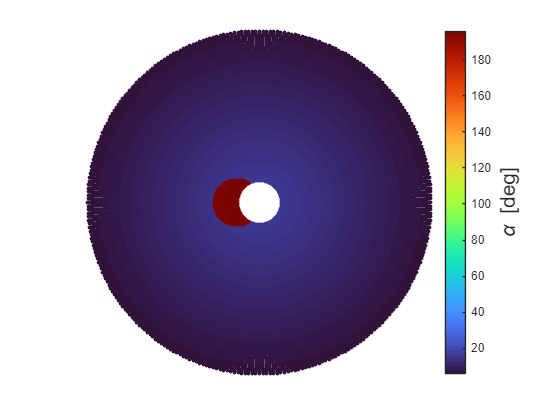

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).alpha;
end
polarPlot(azimutes, rho, values, "", "\alpha [deg]", "./studies/rotor_analysis/sim_B/plots/alpha.eps")

#### Coeficiente de Sustentação

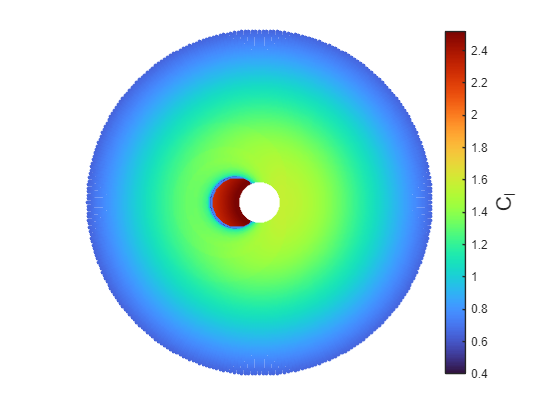

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Cl;
end
polarPlot(azimutes, rho, values, "", "C_l", "./studies/rotor_analysis/sim_B/plots/cl.eps")

#### Coeficiente de Arrasto

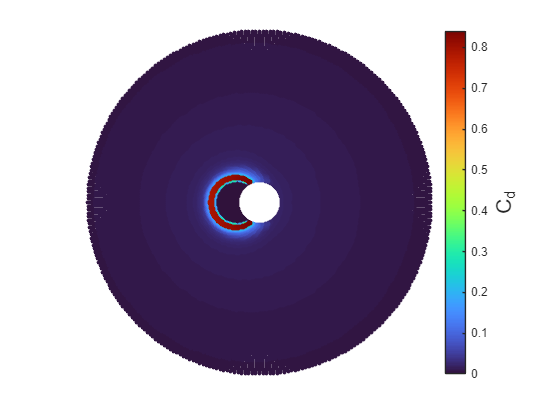

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).Cd;
end
polarPlot(azimutes, rho, values, "", "C_d", "./studies/rotor_analysis/sim_B/plots/cd.eps")

#### Perdas de ponta

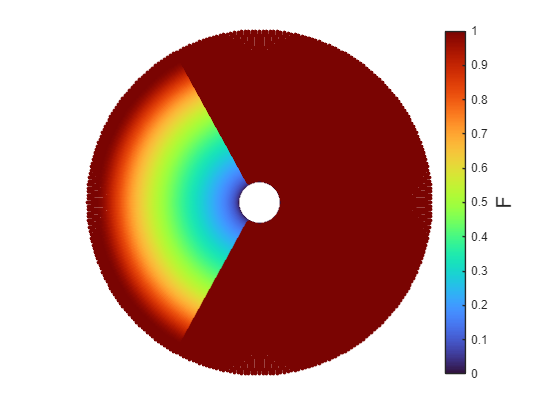

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).f_prandtl;
end
polarPlot(azimutes, rho, values, "", "F", "./studies/rotor_analysis/sim_B/plots/f_prandtl.eps")

#### Força em X - referencial do aerodinâmico

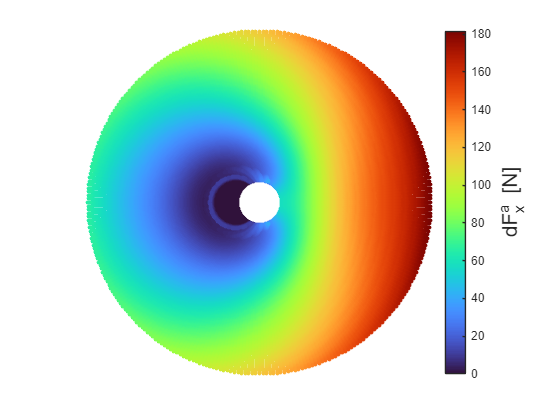

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(1, :);
end
polarPlot(azimutes, rho, values, "", "dF^a_x [N]","./studies/rotor_analysis/sim_B/plots/dFx_a.eps")

#### Força em Y - referencial do aerodinâmico

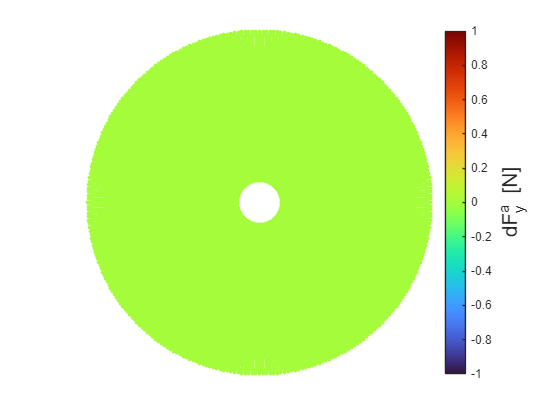

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(2, :);
end
polarPlot(azimutes, rho, values, "", "dF^a_y [N]", "./studies/rotor_analysis/sim_B/plots/dFy_a.eps")

#### Força em Z - referencial do aerodinâmico

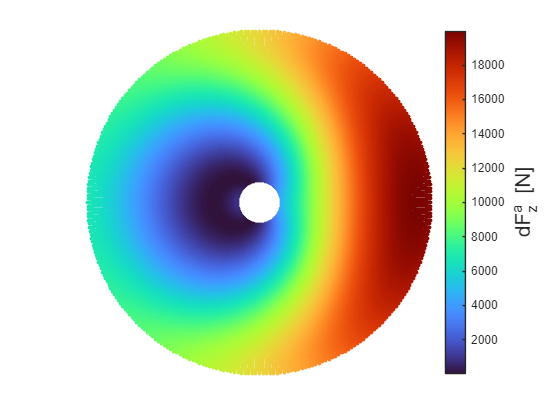

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_a(3, :);
end
polarPlot(azimutes, rho, values, "", "dF^a_z [N]", "./studies/rotor_analysis/sim_B/plots/dFz_a.eps")

#### Força em X - referencial da pá

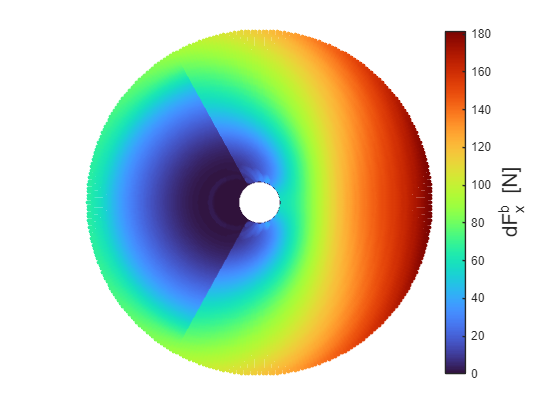

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_e(1, :);
end
polarPlot(azimutes, rho, values, "", "dF^b_x [N]", "./studies/rotor_analysis/sim_B/plots/dFx_r.eps")

#### Força em Y - referencial da pá

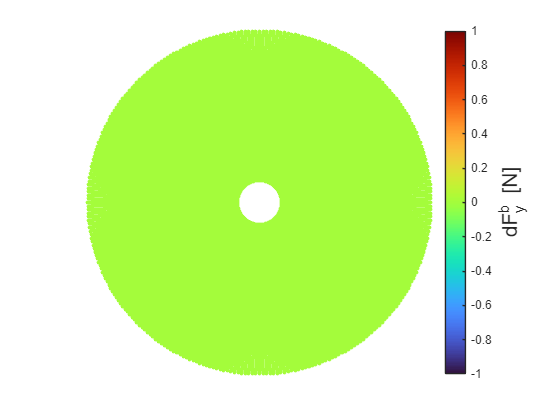

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_e(2, :);
end
polarPlot(azimutes, rho, values, "", "dF^b_y [N]", "./studies/rotor_analysis/sim_B/plots/dFy_r.eps")

#### Força em Z - referencial da pá

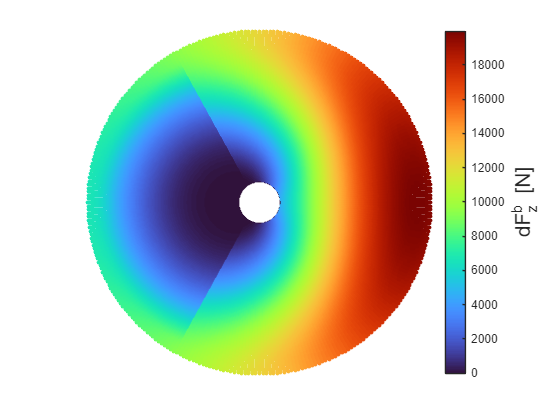

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_e(3, :);
end
polarPlot(azimutes, rho, values, "", "dF^b_z [N]", "./studies/rotor_analysis/sim_B/plots/dFz_r.eps")

#### Força em X - referencial do rotor

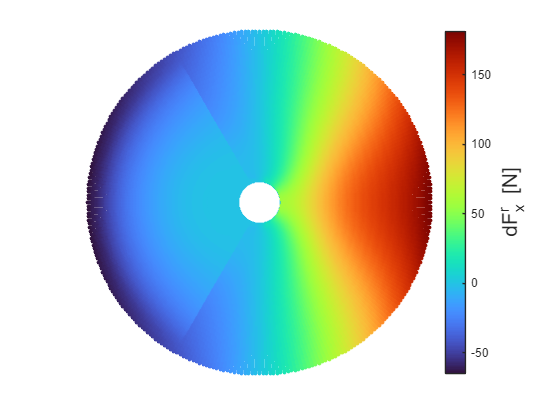

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(1, :);
end
polarPlot(azimutes, rho, values, "", "dF^r_x [N]", "./studies/rotor_analysis/sim_B/plots/dFx_r.eps")

#### Força em Y - referencial do rotor

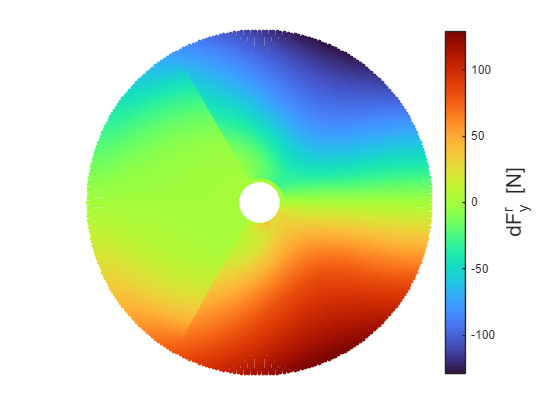

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(2, :);
end
polarPlot(azimutes, rho, values, "", "dF^r_y [N]", "./studies/rotor_analysis/sim_B/plots/dFy_r.eps")

#### Força em Z - referencial do rotor

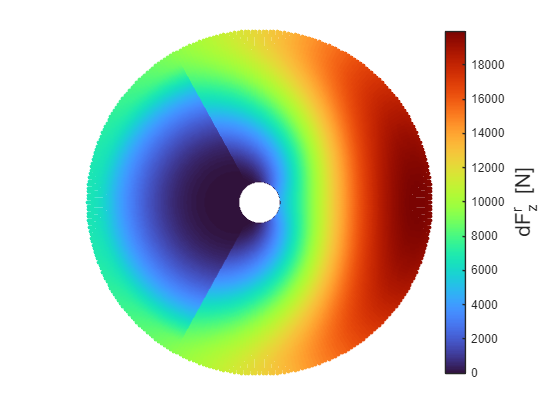

for i=1:length(azimutes)
    values(i, :) = rotor_distribution_data.blade_distribution_data(i).dF_r(3, :);
end
polarPlot(azimutes, rho, values, "", "dF^r_z [N]", "./studies/rotor_analysis/sim_B/plots/dFz_r.eps")